## **Newton-Raphson법**

**1. ****Newton-Raphson법의 정의**

- **Newton-Raphson법**은 비선형 방정식의 근을 찾는 데 가장 많이 사용되는 반복적인 수치해법 중 하나.

- 초기 추정값 $x_0$�을 기반으로 연속적으로 근사하여 정확한 근에 수렴하는 방법.

**2. ****Newton-Raphson 공식**

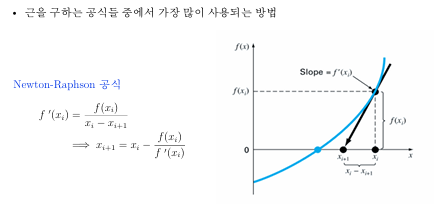

- 근을 찾기 위한 반복식은 다음과 같이 정의됨: $x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$�

- 여기서 $f(x)$는 함수이고, $f\prime (x)$는 그 도함수.

- 기울기(Slope)를 이용하여 현재 위치에서 다음 추정값으로 이동하는 방식.

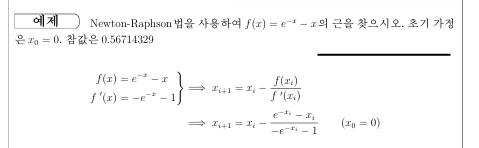

**3. 예제: **$f(x) = e^{-x} - x$**의 근 찾기**

- 초기 추정값을 $x_0 = 0$으로 설정하고 Newton-Raphson 방법을 적용.

- 반복 계산을 통해 다음과 같은 결과를 얻음:

- 1차 반복: 근사값 $x_1 = 0.5$, 상대 오차$\varepsilon_t = 11.8\%$

- 2차 반복: 근사값 $x_2 = 0.566311003$, 상대 오차 $\varepsilon_t = 0.147\%$

- 4차 반복까지 진행하여 최종 근사값 $x = 0.567143290$에 도달.

**4. ****Newton-Raphson법의 특징**

- **수렴 속도**: 초기 추정값이 함수의 실제 근에 가까울수록 빠르게 수렴.

- **함수와 도함수 계산**: 각 반복 단계에서 $f(x)$와 $f\prime (x)$를 계산해야 함.

- **수렴 및 발산**: 초기값이 적절하지 않으면 수렴하지 않거나 발산할 수 있음.

**5. ****실제 활용 사례**

- **공학 및 과학 계산**: 방정식의 근을 찾는 수치해석 문제에서 광범위하게 사용.

- **전기회로 해석**: 복잡한 회로의 임피던스나 전류 계산에 활용.

Newton-Raphson Iterations:
    Iteration     Root      Relative_Error(%)    True_Error(%)
    _________    _______    _________________    _____________

        1            0.5              100             11.839  
        2        0.56631           11.709            0.14675  
        3        0.56714          0.14673         2.2034e-05  
        4        0.56714       2.2106e-05         7.2254e-08  
        5        0.56714       5.0897e-13         7.2254e-08  



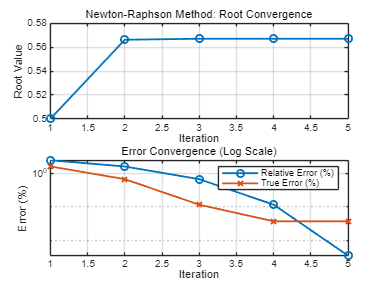

Fixed Initial Guess Iterations:
    Initial_Guess     Root      Relative_Error(%)    True_Error(%)    Iterations
    _____________    _______    _________________    _____________    __________

           1         0.56714       1.9576e-14         7.2254e-08          5     
        0.75         0.56714       1.1112e-09         7.2254e-08          4     
         0.5         0.56714       5.0897e-13         7.2254e-08          4     
        0.25         0.56714       1.9576e-14         7.2254e-08          5     
           0         0.56714       5.0897e-13         7.2254e-08          5     



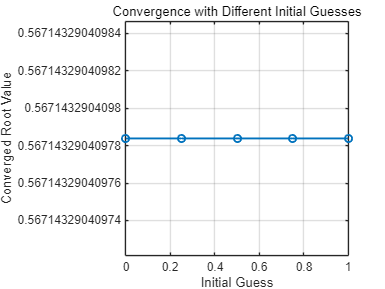

function NA7_1_NewtonRaphson(x)
    % 함수 및 도함수 정의
    func = @(x) exp(-x) - x;
    dfunc = @(x) -exp(-x) - 1;

    x_true = 0.56714329; % 실제 근
    
    % 초기값 설정
    err_g = 0.5e-10; % 허용 오차
    x_new = x; 
    iter = 0;
    
    % 첫 번째 표를 위한 결과 저장
    results = []; % [Iteration, x_value, True_Error]
    
    % Newton-Raphson 반복 계산
    while true % for문 형태로도 가능하다, 횟수지정 
        iter = iter + 1; % 반복 횟수 증가
        x_old = x_new; % 이전 값 저장
        x_new = x_new - func(x_new) / dfunc(x_new); % Newton-Raphson 공식 적용
        
        % 상대 오차 계산
        err_a = abs((x_new - x_old) / (x_new)); % 상대 오차
        err_t = abs((x_new - x_true) / (x_true)); % 참 상대 오차
        
        % 결과 저장 (진행된 횟수, 현재 근사값, 상대 오차, 참 오차)
        results = [results; iter, x_new, err_a * 100, err_t * 100];
        
        % 종료 조건 확인
        if (err_a <= err_g), break; end % 상대 오차가 허용 오차 이하면 종료
        if iter >= 20, break; end % 개구간법에서는 함수가 발산할 수 도 있기 때문에 횟수제한을 정해줘야 함 
    end
    
    % 결과를 표로 변환하여 출력
    T1 = array2table(results, 'VariableNames', {'Iteration', 'Root', 'Relative_Error(%)', 'True_Error(%)'});
    disp('Newton-Raphson Iterations:');
    disp(T1);
    
    % 첫 번째 표의 시각화: Newton-Raphson 수렴 과정
    figure;
    subplot(2,1,1); % 첫 번째 그래프
    plot(results(:,1), results(:,2), '-o', 'LineWidth', 1.5);
    xlabel('Iteration');
    ylabel('Root Value');
    title('Newton-Raphson Method: Root Convergence');
    grid on;
    
    % 두 번째 그래프: 상대 오차와 참 상대 오차
    subplot(2,1,2); % 두 번째 그래프
    semilogy(results(:,1), results(:,3), '-o', 'LineWidth', 1.5, 'DisplayName', 'Relative Error (%)');
    hold on;
    semilogy(results(:,1), results(:,4), '-x', 'LineWidth', 1.5, 'DisplayName', 'True Error (%)');
    xlabel('Iteration');
    ylabel('Error (%)');
    title('Error Convergence (Log Scale)');
    legend('show');
    grid on;
    
    % 두 번째 표의 결과를 위한 초기 근사값 설정
    fixed_results = []; % [Initial Guess, Root, ε_a(%), ε_t(%)]
    for x_initial = linspace(1, 0, 5) % 초기값을 다양하게 설정
        x_new = x_initial;
        iter = 0;
        while true
            iter = iter + 1;
            x_old = x_new;
            x_new = x_new - func(x_new) / dfunc(x_new);
            
            % 상대 오차 및 참 상대 오차 계산
            err_a = abs((x_new - x_old) / (x_new));
            err_t = abs((x_new - x_true) / (x_true));
            
            % 최대 10번 반복
            if iter >= 10 || err_a <= err_g, break; end
        end
        fixed_results = [fixed_results; x_initial, x_new, err_a * 100, err_t * 100, iter];
    end
    
    % 두 번째 결과 표 출력
    T2 = array2table(fixed_results, 'VariableNames', {'Initial_Guess', 'Root', 'Relative_Error(%)', 'True_Error(%)', 'Iterations'});
    disp('Fixed Initial Guess Iterations:');
    disp(T2);
    
    % 두 번째 표의 시각화: 초기 근사값에 따른 수렴 과정
    figure;
    plot(fixed_results(:,1), fixed_results(:,2), '-o', 'LineWidth', 1.5);
    xlabel('Initial Guess');
    ylabel('Converged Root Value');
    title('Convergence with Different Initial Guesses');
    grid on;
end


% Newton-Raphson 방법 실행 스크립트

% 초기값 설정
initial_guess = 0; % x의 초기 추정값 설정

% Newton-Raphson 함수 호출
NA7_1_NewtonRaphson(initial_guess);

## **7.2 오차 추정과 종료 판정 기준**

**1. ****Taylor 급수를 이용한 유도**

Taylor 급수를 이용하여 함수 $f(x)$를 근사할 수 있습니다.

- Taylor 급수 전개식:


$$f(x) = f(x_i) + f'(x_i)(x - x_i) + \frac{f''(\xi)}{2!}(x - x_i)^2$$


- 여기서 $x$와 $x_i$는 함수의 두 점을 나타내고, $\xi$는 $x_i$와 $x$사이에 위치하는 임의의 값입니다.

- Newton-Raphson 공식 유도 과정에서 Taylor 급수를 적용하면 다음과 같이 근사할 수 있습니다:


$$f(x_{i+1}) \approx f(x_i) + f'(x_i)(x_{i+1} - x_i)$$


- 이때$ f(x_{i+1}) = 0$을 대입하면,

$x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$�

- 이는 Newton-Raphson 공식입니다.

**2. Newton-Raphson 방법의 오차 추정**

Newton-Raphson 방법의 오차 추정은 Taylor 급수를 이용하여 2차 수렴 특성을 나타냅니다.

- **오차 추정 과정**:


$$f(x) = f(x_i) + f'(x_i)(x - x_i) + \frac{f''(\xi)}{2!}(x - x_i)^2            $$



$$0 = f(x_i) + f'(x_i)(x_{i+1} - x_i) + \frac{f''(\xi)}{2!}(x_{i+1} - x_i)^2$$


- 따라서


$$f'(x_i)E_{i+1} + \frac{f''(\xi)}{2!}E_{i+1}^2 = 0$$


- 여기서 $E_{i+1}$은 다음 반복 단계의 오차이며, $E_i = x - x_i$입니다.

- 근사적으로 오차는 다음과 같이 추정됩니다:


$$E_{i+1} \approx \frac{f''(\xi)}{2f'(x_i)}E_i^2$$


- �이는 Newton-Raphson 방법이 **2차 수렴**을 가지는 이유를 보여줍니다. 즉, 반복이 진행될수록 오차가 제곱으로 감소합니다.

**결론**

- **Newton-Raphson 방법**은 2차 수렴 특성 덕분에 초기값이 정확할수록 빠르게 수렴합니다.

- Taylor 급수의 확장으로 오차 추정이 가능하며, 이를 통해 수렴 속도를 평가할 수 있습니다.

## **Newton-Raphson 방법의 수식 유도에 대한 상세 설명**

**1. ****Taylor 급수 전개를 이용한 Newton-Raphson 방법의 유도**

Taylor 급수를 활용하여 함수$ f(x)$를$x = x_i$ 주변에서 근사화해 봅시다.

**(1) Taylor 급수의 기본 식**

- 함수 $f(x)$가 $x_i$�에서 충분히 미분 가능하다고 가정할 때, Taylor 급수로 표현하면: 


$$f(x) = f(x_i) + f'(x_i)(x - x_i) + \frac{f''(x_i)}{2!}(x - x_i)^2 + \cdots$$


- 여기서 $x$는$x_i$� 주변의 점을 나타내며, 고차항은 무시하고 첫 두 항만을 고려하면 다음과 같이 근사화할 수 있습니다:


$$f(x) \approx f(x_i) + f'(x_i)(x - x_i)$$


**(2) Newton-Raphson 공식 유도**

- Newton-Raphson 방법은$f(x) = 0$의 근을 찾는 것이 목표입니다.

- 따라서, 근 $x_{i+1}$에서 $f(x_{i+1}) = 0$이 된다고 가정하면 위의 Taylor 급수 식에서 다음과 같이 유도됩니다: 


$$0 = f(x_i) + f'(x_i)(x_{i+1} - x_i)$$


- 이 식을 $x_{i+1}$�에 대해 풀면: 

$x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$�

- 이 식이 바로 Newton-Raphson 반복 공식입니다.

**2. ****오차 추정 과정**

Newton-Raphson 방법의 정확성을 확인하기 위해 오차 추정 과정을 자세히 살펴보겠습니다.

**(1) 오차의 정의**

- 진정한 근을 $x$라고 하고, iii번째 반복에서의 근사값을 $x_i$라고 하면, 오차는 다음과 같이 정의됩니다: 

$E_i = x - x_i$�

**(2) 오차를 Taylor 급수로 표현**

- Taylor 급수로$ f(x)$를 $x_i$ 주변에서 전개해 보겠습니다:


$$f(x) = f(x_i) + f'(x_i)(x - x_i) + \frac{f''(\xi)}{2!}(x - x_i)^2$$


- 여기서 $\xi$는 $x$와 $x_i$ 사이의 임의의 점입니다.

- $x$가 정확한 근이기 때문에 $f(x) = 0$입니다. 따라서 위 식을 0으로 놓고 정리하면:


$$0 = f(x_i) + f'(x_i)(x - x_i) + \frac{f''(\xi)}{2!}(x - x_i)^2$$


- 이를 Newton-Raphson 방법의 관점에서 다시 작성하면:


$$f(x_i) = -f'(x_i)(x - x_i) - \frac{f''(\xi)}{2!}(x - x_i)^2$$


**(3) 다음 반복에서의 오차 계산**

- Newton-Raphson 공식에 따라 다음 반복 근사값 $x_{i+1}$은:

$x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$�

- 오차 $E_{i+1} = x - x_{i+1}$을 구해 보겠습니다. $x_{i+1}$을 $x$에 대한 표현식에 대입하면:


$$E_{i+1} = x - x_{i+1} = x - \left( x_i - \frac{f(x_i)}{f'(x_i)} \right)     $$


$          E_{i+1} = E_i - \frac{f(x_i)}{f'(x_i)}$�

- 여기서 $f(x_i)$을 Taylor 급수로부터의 근사식을 대입하면:


$$E_{i+1} = E_i - \frac{-f'(x_i)E_i - \frac{f''(\xi)}{2!}E_i^2}{f'(x_i)}                 $$



$$= E_i + E_i - \frac{f''(\xi)}{2f'(x_i)}E_i^2             $$


$E_{i+1} = \frac{f''(\xi)}{2f'(x_i)}E_i^2$�

**(4) 수렴 속도**

- Newton-Raphson 방법의 오차 추정식이 $E_{i+1} = C \cdot E_i^2$형태이므로, Newton-Raphson 방법은 **2차 수렴**을 갖습니다.

- 즉, 초기값이 근에 가까울수록 오차가 제곱으로 감소하므로 수렴 속도가 매우 빠릅니다.

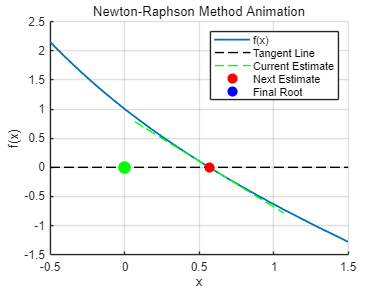

% 주어진 함수 및 도함수 정의
f = @(x) exp(-x) - x;          % f(x) = e^(-x) - x
df = @(x) -exp(-x) - 1;        % f'(x) = -e^(-x) - 1

% 초기 설정
x0 = 0;                        % 초기 추정값
maxIterations = 10;            % 최대 반복 횟수
tolerance = 1e-10;             % 허용 오차
gifFilename = 'Newton_Raphson_Animation.gif';  % 저장할 GIF 파일명

% Newton-Raphson 반복 과정 수행
iterations = zeros(1, maxIterations + 1);
iterations(1) = x0;

for i = 1:maxIterations
    % Newton-Raphson 공식 적용
    x_new = iterations(i) - f(iterations(i)) / df(iterations(i));
    
    % 수렴 여부 확인
    if abs(x_new - iterations(i)) < tolerance
        iterations = iterations(1:i + 1);
        break;
    end
    
    % 새로운 추정값 저장
    iterations(i + 1) = x_new;
end

% 그래프 시각화 및 애니메이션 생성
figure;
hold on;
fplot(f, [-0.5, 1.5], 'LineWidth', 1.5); % 주어진 함수 f(x) 그래프
xlabel('x');
ylabel('f(x)');
title('Newton-Raphson Method Animation');
grid on;
plot(xlim, [0 0], 'k--'); % x축 표시
legend('f(x)');

% GIF 파일로 저장하기 위한 루프
for n = 1:length(iterations) - 1
    currentX = iterations(n);
    nextX = iterations(n + 1);
    

    % 현재 근사값에서의 접선 방정식 계산
    tangentLine = @(x) f(currentX) + df(currentX) * (x - currentX);
    
    % 현재 단계의 접선 및 점 표시
    h_tangent = fplot(tangentLine, [currentX - 0.5, currentX + 0.5], '--g');
    h_currentPoint = plot(currentX, f(currentX), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    h_nextPoint = plot(nextX, 0, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    
    % 그래프 업데이트 및 현재 프레임 저장
    drawnow;
    frame = getframe(gcf); % 현재 프레임을 캡처
    im = frame2im(frame); % 캡처한 프레임을 이미지로 변환
    [imind, cm] = rgb2ind(im, 256); % 인덱스화하여 GIF 형식으로 변환
    
    % GIF 파일 저장
    if n == 1
        imwrite(imind, cm, gifFilename, 'gif', 'Loopcount', inf, 'DelayTime', 1);
    else
        imwrite(imind, cm, gifFilename, 'gif', 'WriteMode', 'append', 'DelayTime', 1);
    end
    
    % 이전 단계의 접선과 점 제거
    if n < length(iterations) - 1
        delete(h_tangent);
        delete(h_currentPoint);
        delete(h_nextPoint);
    end
end

% 최종 근 표시
plot(iterations(end), 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
legend('f(x)', 'Tangent Line', 'Current Estimate', 'Next Estimate', 'Final Root');
hold off;


## Newton-Raphson 방법의 문제점

Newton-Raphson `방법을` `사용하여`$ f(x) = x^{10} - 1$ `의` `양의` `근을` `구하는` `방법`

초기 추정값 x₀ = 0.5


$$x_{i+1} = x_i - \frac{x_i^{10} - 1}{10x_i^{9}}$$


% Newton-Raphson 방법을 사용하여 f(x) = x^10 - 1의 양의 근을 찾는 코드
% 초기 추정값 설정
x0 = 0.5;                      % 초기값

Iteration    Root               ε_a(%)             ε_t(%)


maxIterations = 50;            % 최대 반복 횟수

   1.0e+03 *

    0.0010    0.0517       NaN    5.0650
    0.0020    0.0465    0.0111    4.5485
    0.0030    0.0418    0.0111    4.0837
    0.0040    0.0377    0.0111    3.6653
    0.0050    0.0339    0.0111    3.2888
    0.0060    0.0305    0.0111    2.9499
    0.0070    0.0274    0.0111    2.6449
    0.0080    0.0247    0.0111    2.3704
    0.0090    0.0222    0.0111    2.1234
    0.0100    0.0200    0.0111    1.9010
    0.0110    0.0180    0.0111    1.7009
    0.0120    0.0162    0.0111    1.5208
    0.0130    0.0146    0.0111    1.3587
    0.0140    0.0131    0.0111    1.2129
    0.0150    0.0118    0.0111    1.0816
    0.0160    0.0106    0.0111    0.9634
    0.0170    0.0096    0.0111    0.8571
    0.0180    0.0086    0.0111    0.7614
    0.0190    0.0078    0.0111    0.6752
    0.0200    0.0070    0.0111    0.5977
    0.0210    0.0063    0.0111    0.5279
    0.0220    0.0057    0.0111    0.4651
    0.0230    0.0051    0.0111    0.4086
    0.0240    0.0046    0.0111    0.3578
  

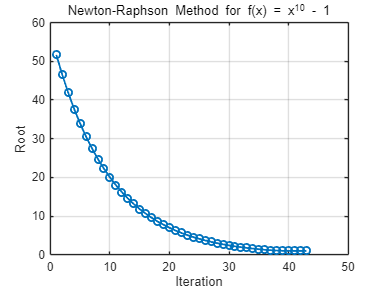

tolerance = 1e-10;             % 허용 오차 (tolerance)

% 방정식과 그 도함수 정의
f = @(x) x^10 - 1;             % 주어진 함수 f(x)
df = @(x) 10 * x^9;            % 도함수 f'(x)

% Newton-Raphson 반복 수행
x = x0;                        % 초기값 설정
true_root = 1;                 % 참값 (f(x) = 0 의 근)

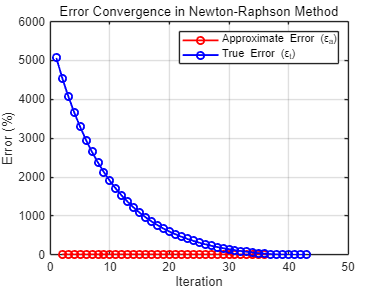

results = [];                  % 결과를 저장할 배열

for iter = 1:maxIterations
    % Newton-Raphson 공식 적용
    x_new = x - f(x) / df(x);
    
    % 근사상태오차와 참상태오차 계산
    if iter > 1
        ea = abs((x_new - x) / x_new) * 100;  % 근사상태오차 ε_a
    else
        ea = NaN;  % 첫 번째 반복에서는 이전값이 없으므로 근사상태오차 계산 불가

    end
    et = abs((true_root - x_new) / true_root) * 100;  % 참상태오차 ε_t
    
    % 결과 저장 (Iter, root, ε_a, ε_t)
    results = [results; iter, x_new, ea, et];
    
    % 오차가 허용 오차 이내로 수렴했는지 확인
    if abs(f(x_new)) < tolerance
        break;
    end
    
    % x 업데이트
    x = x_new;
end

% 결과 출력
disp('Iteration    Root               ε_a(%)             ε_t(%)');
disp(results);

% 그래프 그리기
figure;
plot(results(:,1), results(:,2), '-o', 'LineWidth', 1.5, 'MarkerSize', 6);
hold on;
xlabel('Iteration');
ylabel('Root');
title('Newton-Raphson Method for f(x) = x^{10} - 1');
grid on;

% ε_a와 ε_t에 대한 그래프
figure;
plot(results(:,1), results(:,3), 'r-o', 'LineWidth', 1.5, 'MarkerSize', 6); % 근사상태오차 ε_a
hold on;
plot(results(:,1), results(:,4), 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6); % 참상태오차 ε_t
xlabel('Iteration');
ylabel('Error (%)');
legend({'Approximate Error (ε_a)', 'True Error (ε_t)'}, 'Location', 'northeast');
title('Error Convergence in Newton-Raphson Method');
grid on;

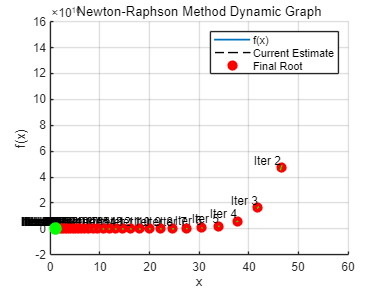

% Newton-Raphson 방법을 사용하여 f(x) = x^10 - 1의 양의 근을 찾는 코드 
% 초기 추정값 설정
x0 = 0.5;                      % 초기값
maxIterations = 50;            % 최대 반복 횟수
tolerance = 1e-10;             % 허용 오차 (tolerance)


% 방정식과 그 도함수 정의 (벡터화)
f = @(x) x.^10 - 1;            % 주어진 함수 f(x), 벡터화: .^ 연산자 사용

Iteration    Root               ε_a(%)             ε_t(%)


df = @(x) 10 * x.^9;           % 도함수 f'(x), 벡터화: .^ 연산자 사용

   1.0e+03 *

    0.0010    0.0517       NaN    5.0650
    0.0020    0.0465    0.0111    4.5485
    0.0030    0.0418    0.0111    4.0837
    0.0040    0.0377    0.0111    3.6653
    0.0050    0.0339    0.0111    3.2888
    0.0060    0.0305    0.0111    2.9499
    0.0070    0.0274    0.0111    2.6449
    0.0080    0.0247    0.0111    2.3704
    0.0090    0.0222    0.0111    2.1234
    0.0100    0.0200    0.0111    1.9010
    0.0110    0.0180    0.0111    1.7009
    0.0120    0.0162    0.0111    1.5208
    0.0130    0.0146    0.0111    1.3587
    0.0140    0.0131    0.0111    1.2129
    0.0150    0.0118    0.0111    1.0816
    0.0160    0.0106    0.0111    0.9634
    0.0170    0.0096    0.0111    0.8571
    0.0180    0.0086    0.0111    0.7614
    0.0190    0.0078    0.0111    0.6752
    0.0200    0.0070    0.0111    0.5977
    0.0210    0.0063    0.0111    0.5279
    0.0220    0.0057    0.0111    0.4651
    0.0230    0.0051    0.0111    0.4086
    0.0240    0.0046    0.0111    0.3578
  

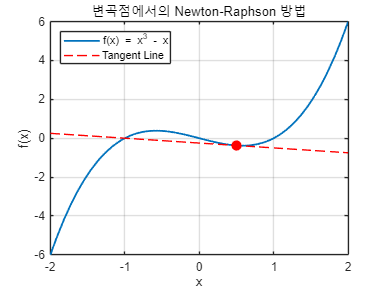


% Newton-Raphson 반복 수행
x = x0;                        % 초기값 설정
true_root = 1;                 % 참값 (f(x) = 0 의 근)
results = [];                  % 결과를 저장할 배열

% 동적 그래프를 위한 설정
figure;
hold on;
fplot(f, [0, 2], 'LineWidth', 1.5);  % 주어진 함수 f(x) 그래프 그리기
xlabel('x');
ylabel('f(x)');
title('Newton-Raphson Method Dynamic Graph');
grid on;
plot(xlim, [0 0], 'k--'); % x축 표시
%legend('f(x)');

% 동적 그래프 애니메이션
for iter = 1:maxIterations
    % Newton-Raphson 공식 적용
    x_new = x - f(x) / df(x);
    
    % 근사상태오차와 참상태오차 계산
    if iter > 1
        ea = abs((x_new - x) / x_new) * 100;  % 근사상태오차 ε_a
    else
        ea = NaN;  % 첫 번째 반복에서는 이전값이 없으므로 근사상태오차 계산 불가
    end
    et = abs((true_root - x_new) / true_root) * 100;  % 참상태오차 ε_t
    
    % 결과 저장 (Iter, root, ε_a, ε_t)
    results = [results; iter, x_new, ea, et];

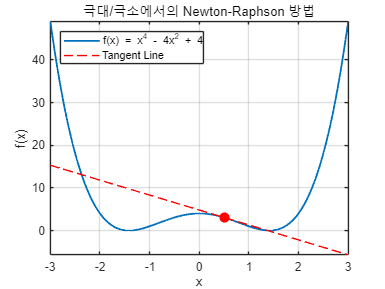

    
    % 동적 그래프에서 현재 추정값 표시
    plot(x_new, f(x_new), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    text(x_new, f(x_new), sprintf(' Iter %d', iter), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
    
    % 접선의 기울기를 사용하여 현재 지점에서 접선 그리기
    tangentLine = @(x) f(x_new) + df(x_new)*(x - x_new); % 접선 함수 정의
    fplot(tangentLine, [x_new - 0.2, x_new + 0.2], '--g'); % 접선 표시
    
    % 수렴 과정 보여주기
    pause(1); % 1초 대기하여 동적 효과 제공
    
    % 오차가 허용 오차 이내로 수렴했는지 확인
    if abs(f(x_new)) < tolerance
        break;
    end
    
    % x 업데이트

    x = x_new;
end

% 최종 결과 출력 및 표시
plot(x_new, 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
legend('f(x)', 'Current Estimate', 'Final Root');
hold off;

% 결과 표 출력
disp('Iteration    Root               ε_a(%)             ε_t(%)');
disp(results);

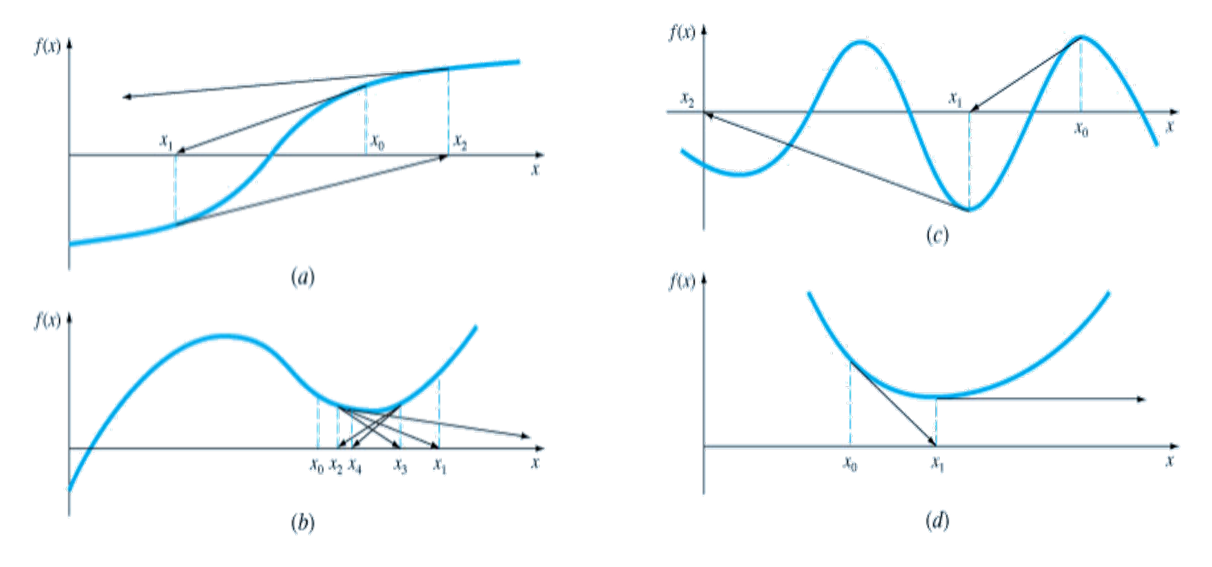

a) 변곡점의 존재 ($f''(x) = 0$)

b) 극대, 극소에서 진동 ($f'(x) \approx 0$)

c) 초기 예상했던 근에서 벗어나 다른 근을 찾는 경우

d) $f'(x) = 0$인 경우

**그래프 (a): 변곡점의 존재 (**$f''(x) = 0$**)**

- **설명**: Newton-Raphson 방법이 변곡점에서 작동할 때 $f'(x) \neq 0$이지만$f''(x) = 0$인 경우 접선이 $x$-축과 멀리 교차할 수 있어 수렴하지 않을 수 있습니다.

- **예시 수식**:$f(x) = x^3 - x$

- 이 함수는 $x = 0$에서 변곡점을 갖고 있습니다.

- Newton-Raphson 공식: $x_{n+1} = x_n - \frac{f(x_n)}{f'(x_n)} = x_n - \frac{x_n^3 - x_n}{3x_n^2 - 1}$��

**그래프 (b): 극대, 극소에서 진동 (**$f'(x) \approx 0$**)**

- **설명**: 극대나 극소에서$f'(x) \approx 0$인 경우, Newton-Raphson 방법은 다음 추정값을 계산할 때 큰 변화가 없거나 느리게 수렴하거나 발산할 수 있습니다.

- **예시 수식**:$f(x) = x^4 - 4x^2 + 4$

- 이 함수는 $x = 1$과 $x = -1$에서 극소점과 극대점을 갖고 있습니다.

- Newton-Raphson 공식: $x_{n+1} = x_n - \frac{x_n^4 - 4x_n^2 + 4}{4x_n^3 - 8x_n}$�

**그래프 (c): 초기 예상했던 근에서 벗어나 다른 근을 찾는 경우**

- **설명**: Newton-Raphson 방법이 시작값에 따라 다른 근으로 수렴하거나, 심지어 수렴하지 않을 수도 있습니다.

- **예시 수식**: $f(x) = (x - 1)(x + 2)(x - 3)$

- 이 다항식은$x = 1, x = -2, x = 3$에서 근을 갖습니다.

- 초기값 $x_0$�에 따라 수렴하는 근이 다를 수 있습니다.

- Newton-Raphson 공식:$x_{n+1} = x_n - \frac{(x_n - 1)(x_n + 2)(x_n - 3)}{3x_n^2 - 2x_n - 5}$�

**그래프 (d): **$f'(x) = 0$**인 경우**

- **설명**: $f'(x) = 0$인 경우에는 접선이 $x$-축과 평행하게 되기 때문에 Newton-Raphson 방법이 진행되지 않거나 발산합니다.

- **예시 수식**:$f(x) = x^3 - 3x + 2$

- 이 함수는 $x = 1$에서 $f'(x) = 0$이 됩니다.

- Newton-Raphson 공식: $x_{n+1} = x_n - \frac{x_n^3 - 3x_n + 2}{3x_n^2 - 3}$

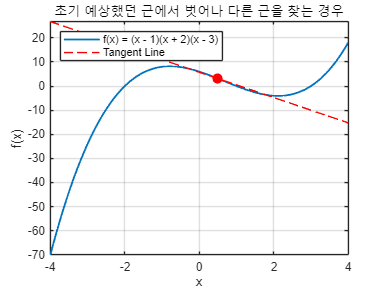

% 그래프 (a) 변곡점의 존재 (f''(x) = 0)
figure;
f = @(x) x.^3 - x; % 함수 정의
df = @(x) 3*x.^2 - 1; % 도함수 정의

fplot(f, [-2, 2], 'LineWidth', 1.5); % 함수 그래프
hold on;

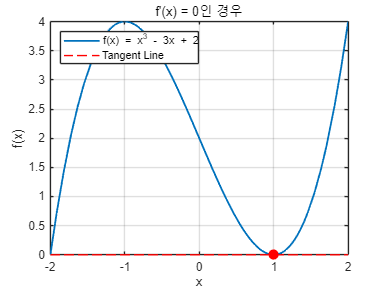

x0 = 0.5; % 초기값 설정
tangent = @(x) f(x0) + df(x0)*(x - x0); % 접선 방정식
fplot(tangent, [-2, 2], '--r'); % 접선 그래프
plot(x0, f(x0), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 접선 시작점 표시
xlabel('x');
ylabel('f(x)');
title('변곡점에서의 Newton-Raphson 방법');
grid on;
legend('f(x) = x^3 - x', 'Tangent Line', 'Location', 'northwest');
hold off;

% 그래프 (b) 극대, 극소에서 진동 (f'(x) ≈ 0)
figure;
f = @(x) x.^4 - 4*x.^2 + 4; % 함수 정의
df = @(x) 4*x.^3 - 8*x; % 도함수 정의

fplot(f, [-3, 3], 'LineWidth', 1.5); % 함수 그래프
hold on;

x0 = 0.5; % 초기값 설정
tangent = @(x) f(x0) + df(x0)*(x - x0); % 접선 방정식
fplot(tangent, [-3, 3], '--r'); % 접선 그래프
plot(x0, f(x0), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 접선 시작점 표시
xlabel('x');
ylabel('f(x)');
title('극대/극소에서의 Newton-Raphson 방법');
grid on;
legend('f(x) = x^4 - 4x^2 + 4', 'Tangent Line', 'Location', 'northwest');
hold off;

% 그래프 (c) 초기 예상했던 근에서 벗어나 다른 근을 찾는 경우
figure;
f = @(x) (x - 1).*(x + 2).*(x - 3); % 함수 정의
df = @(x) 3*x.^2 - 2*x - 5; % 도함수 정의

fplot(f, [-4, 4], 'LineWidth', 1.5); % 함수 그래프
hold on;
x0 = 0.5; % 초기값 설정
tangent = @(x) f(x0) + df(x0)*(x - x0); % 접선 방정식
fplot(tangent, [-4, 4], '--r'); % 접선 그래프
plot(x0, f(x0), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 접선 시작점 표시
xlabel('x');
ylabel('f(x)');
title('초기 예상했던 근에서 벗어나 다른 근을 찾는 경우');
grid on;
legend('f(x) = (x - 1)(x + 2)(x - 3)', 'Tangent Line', 'Location', 'northwest');
hold off;

% 그래프 (d) f'(x) = 0인 경우
figure;
f = @(x) x.^3 - 3*x + 2; % 함수 정의
df = @(x) 3*x.^2 - 3; % 도함수 정의

fplot(f, [-2, 2], 'LineWidth', 1.5); % 함수 그래프
hold on;
x0 = 1; % 초기값 설정
tangent = @(x) f(x0) + df(x0)*(x - x0); % 접선 방정식
fplot(tangent, [-2, 2], '--r'); % 접선 그래프
plot(x0, f(x0), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 접선 시작점 표시
xlabel('x');
ylabel('f(x)');
title('f''(x) = 0인 경우');
grid on;
legend('f(x) = x^3 - 3x + 2', 'Tangent Line', 'Location', 'northwest');
hold off;


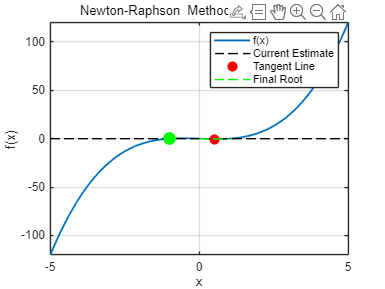

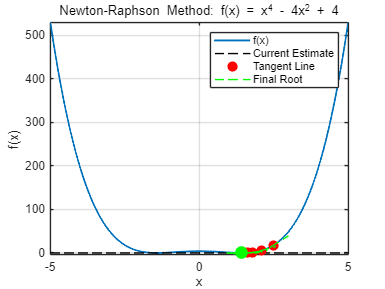

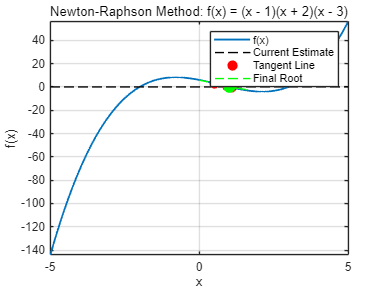

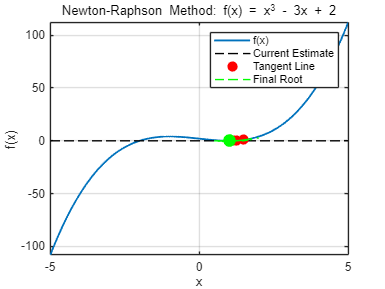

% Newton-Raphson 방법을 사용하여 각각의 함수에 대해 초기값을 임의로 설정하고 해를 찾는 과정을 시각화하는 코드

% 함수 목록과 그 도함수 정의
functions = {@(x) x.^3 - x, @(x) x.^4 - 4*x.^2 + 4, @(x) (x - 1).*(x + 2).*(x - 3), @(x) x.^3 - 3*x + 2};
derivatives = {@(x) 3*x.^2 - 1, @(x) 4*x.^3 - 8*x, @(x) 3*x.^2 - 2*x - 5, @(x) 3*x.^2 - 3};

% 초기값 목록 설정 (각 함수마다)
initial_values = [0.5, 2.5, 0.5, 1.5];

% 그래프 타이틀 목록
titles = {'f(x) = x^3 - x', 'f(x) = x^4 - 4x^2 + 4', 'f(x) = (x - 1)(x + 2)(x - 3)', 'f(x) = x^3 - 3x + 2'};

% 반복 횟수와 허용 오차 설정
maxIterations = 50;
tolerance = 1e-6;

for i = 1:4
    % 현재 함수와 도함수 설정
    f = functions{i};

    df = derivatives{i};
    x0 = initial_values(i); % 초기값
    
    % 그래프 설정
    figure;
    fplot(f, [-5, 5], 'LineWidth', 1.5); % 주어진 함수 f(x) 그래프 그리기
    hold on;
    xlabel('x');
    ylabel('f(x)');
    title(['Newton-Raphson Method: ', titles{i}]);
    grid on;
    plot(xlim, [0 0], 'k--'); % x축 표시
    
    % Newton-Raphson 반복 수행
    x = x0;
    for iter = 1:maxIterations
        % Newton-Raphson 공식 적용
        x_new = x - f(x) / df(x);
        
        % 현재 점과 접선 그리기
        plot(x, f(x), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 현재 추정값
        tangent = @(t) f(x) + df(x)*(t - x); % 접선 방정식
        fplot(tangent, [x - 0.5, x + 0.5], '--g'); % 접선 그래프
        
        % 현재 근사상태오차 계산
        ea = abs((x_new - x) / x_new) * 100;
        
        % 수렴 판정
        if abs(f(x_new)) < tolerance || ea < tolerance
            break;
        end
        
        % x 업데이트
        x = x_new;
        
        % 수렴 과정 보여주기
        pause(1); % 1초 대기하여 동적 효과 제공
    end
    
    % 최종 근 표시
    plot(x_new, 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    legend('f(x)', 'Current Estimate', 'Tangent Line', 'Final Root');
    
    hold off;
end


**Newton-Raphson 법의 문제점**

- 일반적인 수렴 판정 기준이 존재하지 않음

- 수렴은 함수의 성질과 초기 가정의 정확도에 의존

- 도함수 계산이 어렵거나 계산량이 늘어날 수 있음

- $f'(x) \approx 0$ 또는 $f''(x) \approx 0$의 존재

**해결책**

- 그래프 기능 내장

- 계산의 마지막 단계에서 최종 근사값을 함수에 대입해서 결과가 0에 가까운지 검사

- ⇒ 근사값이 근으로부터 멀리 떨어져 수렴이 느려지거나 진동으로 $\epsilon_a$� 값이 작은 경우 대비

- 최대 반복 횟수 제한

- ⇒ 프로그램 수렴이 늦거나 진동 또는 끝없이 발생하는 경우 대비

- 계산 도중 $f'(x) = 0$이 되는 가능성에 대한 검사

�